% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=x; T=2*pi; [-pi;pi]

clear
syms x real;
f(x)=x;

syms m integer;
assume(m>=1)
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = 0$$

$$a(m) = 0$$

$$b(m) = -\frac{2\,{\left(-1\right)}^{m}}{m}$$

$$abf(m) = -\frac{2\,{\left(-1\right)}^{m}\,\sin\left(m\,x\right)}{m}$$

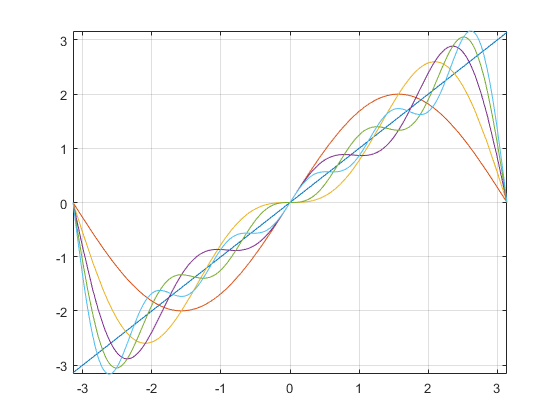


fplot(f(x),[-pi pi]);
hold on;

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-pi pi])
    grid on
end
hold off

f1

$$f1 = \frac{2\,\sin\left(3\,x\right)}{3}-\sin\left(2\,x\right)-\frac{\sin\left(4\,x\right)}{2}+\frac{2\,\sin\left(5\,x\right)}{5}+2\,\sin\left(x\right)$$

% (2*sin(3*x))/3 - sin(2*x) - sin(4*x)/2 + (2*sin(5*x))/5 + 2*sin(x)

a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & 2 & 2\,\sin\left(x\right)\\ 2 & 0 & -1 & -\sin\left(2\,x\right)\\ 3 & 0 & \frac{2}{3} & \frac{2\,\sin\left(3\,x\right)}{3}\\ 4 & 0 & -\frac{1}{2} & -\frac{\sin\left(4\,x\right)}{2}\\ 5 & 0 & \frac{2}{5} & \frac{2\,\sin\left(5\,x\right)}{5} \end{array}\right)$$

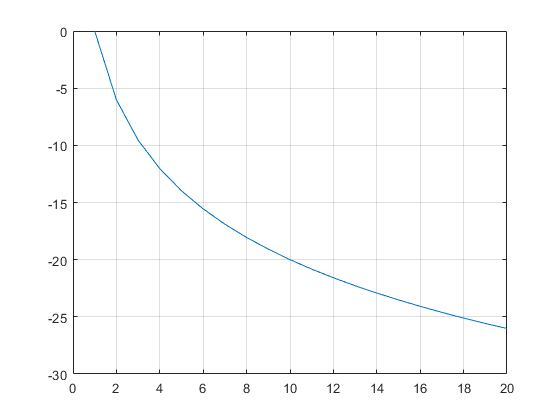

% [ 1, 0,    2,       2*sin(x)]
% [ 2, 0,   -1,      -sin(2*x)]
% [ 3, 0,  2/3, (2*sin(3*x))/3]
% [ 4, 0, -1/2,    -sin(4*x)/2]
% [ 5, 0,  2/5, (2*sin(5*x))/5]

x=0:20;
y(1)=a0/2;
for m=1:20
    y(m+1)=a(m)+1i*b(m);
end
yd=20*log10(abs(y)/abs(y(2)));

plot(x,yd)
grid on;